# Kinematic tree dynamics

Definiamo il grafo dell'albero cinematico inizializzando il parent ed il successor array

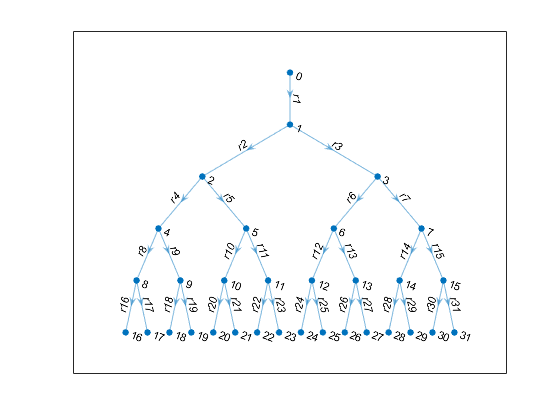

clc; clear all;

%! ricordare di aggiungere CasADi al path di matlab
addpath(genpath('../utils'));
addpath(genpath('../graphics'));

p = [0,1,1,2,2,3,3,4,4,5,5,6,6,7,7,8,8,9,9,10,10,11,11,12,12,13,13,14,14,15,15]; % predecessor array
s = 1:31;                                                                        % successor array

% create the graph (Remember matlab indexing origin starts from 1)
G = digraph(p+1, s+1);

jointLabels =cell(length(s), 1);
nodeLabels = cell(length(s) + 1, 1);
nodeLabels{1} = '0';
for i = 1:length(s)
    jointLabels{i} = ['r' num2str(i)];
    nodeLabels{i+1} = num2str(i);
end
figure;
kinematicTreeGraph = plot(G, 'NodeLabel',nodeLabels, 'EdgeLabel', jointLabels);


% traslazioni dei link
dx = [0,...
      -3.2, 3.2, ...
      repmat([-1.5, 1.5], 1, 2),...
      repmat([-0.8, 0.8], 1, 4),...
      repmat([-0.4, 0.4], 1, 8)];

dy = [0.5, abs(dx(2:end))];

% matrici omogenee di offset
% Per convenzione, l'orientazione dell'asse Z determina l'asse del giunto

gT = nan(4,4,length(dx));

for i = 1:length(dx)
    
    if ismember(i, [2,3])
        
        R = TrotX(pi/2);
        gT(:,:,i) = Tty(dx(i))*Ttz(dy(i))*R;
        
    elseif ismember(i, (4:7))
        
        R = TrotX(-pi/2);
        gT(:,:,i) = R*Tty(dx(i))*Ttz(dy(i));
        
    elseif ismember(i, (16:31))
        
        R = TrotY(pi/2);
        gT(:,:,i) = Tty(dx(i))*Ttz(dy(i))*R;
        
    else
        
        gT(:,:,i) = Ttz(dy(i))*Tty(dx(i));
        
    end 
    
end

Definiamo la tipologia di giunto secondo la notazione del passo d'elica: h = 0 -> giunto rotoidale, h = Inf -> prismatico, elicoidale altrimenti

h(1:length(dx)) = 0; % tutti giunti rotoidali
h(4:7) = Inf; % dal 4 al 7imo giunto li redifinisco prismatici

Create the kinematicTree:

% p ed s definiscono la struttura del grafo;
% gT: matrixi di offset definiscono geometria dei link ed orientazione degli assi di giunto 
% h definisce la tipologia di giunto
X = repmat([0;0;0;0;0;1], 1, 31); % unitary twists
X(:, 4:7) = repmat([0;0;1;0;0;0],1 , 4);
tree = kinematicTree(p, s, gT, X, h);

% inizializziamo i tensori generalizzati di inerzia
for i = 1:tree.Nb
    if i == 1
        mass = 7;
    elseif ismember(i, [2,3])
        mass = 5;
    elseif ismember(i, (4:7))
        mass = 3;
    elseif ismember(i, (8:15))
        mass = 1;
    elseif ismember(i, (16:31))
        mass = 0.5;
    end
    tree.I{i} = eye(6).*mass; % inertia matrices
    tree.I{i}(4:6,4:6) = tree.I{i}(4:6,4:6).*4; % baricentrico
    G_bg =  gT(:,:,i);
    G_bg(1:4, 4) = G_bg(1:4, 4)./2;
    tree.I{i} = adjointStar(G_bg)*tree.I{i}*adjointInv(G_bg); % trasformazione in {B}
end

determinazione dei parent array e lista dei figli (lambda e mu)

lambda = tree.lambda  

lambda =      0     1     1     2     2     3     3     4     4     5     5     6     6     7     7     8     8     9     9    10    10    11    11    12    12    13    13    14    14    15    15


mu = tree.mu         

mu = 1×32 cell array
    {[1]}    {[2 3]}    {[4 5]}    {[6 7]}    {[8 9]}    {[10 11]}    {[12 13]}    {[14 15]}    {[16 17]}    {[18 19]}    {[20 21]}    {[22 23]}    {[24 25]}    {[26 27]}    {[28 29]}    {[30 31]}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}    {1×0 double}


Calcolo della dinamica inversa

Fext = zeros(6,tree.Nb); % external forces on each node

Vroot = [0;0;0;0;0;0]; % twist at root node
Vrootdot = Vroot;      % twist derivative at root node

% inizializziamo velocità ed accelerazioni casuali
q   = rand(1000, tree.Nb); 
qd  = rand(1000, tree.Nb);        % joint velocities
qdd = rand(1000, tree.Nb);        % joint accelerations

% dinamica inversa, calcolo delle tau
tau = nan(1000, tree.Nb);
tic
for i = 1:1000
    [tau(i,:), F] = tree.RNEAdyn(q(i, :),qd(i,:),qdd(i,:),Vroot,Vrootdot,Fext);
end
time = toc;
disp("1000 iterations of RNEA computed in: " + time + " seconds")

1000 iterations of RNEA computed in: 1.9906 seconds


disp("average of " + time + " ms per iteration")

average of 1.9906 ms per iteration


Calcolo della dinamica diretta

qddNew = nan(1000, tree.Nb); % inizializzo delle nuove accelerazioni incognite da trovare

tic
for i = 1:1000
    qddNew(i,:) = tree.ABAdyn(q(i, :),qd(i,:),tau(i,:),Vroot,Vrootdot,Fext);
end
time = toc;

disp("1000 iterations of ABA computed in: " + time + " seconds")

1000 iterations of ABA computed in: 2.5421 seconds


disp("average of " + time + " ms per iteration")

average of 2.5421 ms per iteration



% validiamo i risultati della dinamica diretta (ABA) con quelli della dinamica
% inversa (RNEA)
isequal(chop(qdd-qddNew, 1e-8), zeros(1000, tree.Nb))

ans = logical
   1


Integriamo adesso una simulazione di tale albero cinematico 

Data la difficoltà dell'esprimere un task sensato per una struttura di tali dimensioni (abbiamo 16 end-effectors !!!), si imposta una semplice simulazione dove applichiamo sui giunti delle molle e smorzatori. Si perturba dunque il sistema e si integra.

import casadi.*
q_sym = SX.sym('q', tree.Nb, 1);
qd_sym = SX.sym('qd', tree.Nb, 1);
V0_sym = SX.sym('V0', 6, 1);
V0d_sym = SX.sym('V0d', 6, 1);
Fext_sym = SX.sym('F', 6, tree.Nb);
tau_sym = SX.sym('tau', tree.Nb, 1);

% scriviamo il sistema in forma di stato: xdot = f(x, u)
% stati del sistema
x = [q_sym; qd_sym];
ABA = tree.ABAdynCasadi(q_sym, qd_sym, tau_sym, V0_sym, V0d_sym, Fext_sym).';
xdot = [qd_sym; ABA];

% come ingressi totali del sistema scegliamo u = [tau; V0; V0d; Fext]
u = [tau_sym; V0_sym; V0d_sym; Fext_sym(:)];

xdot_fun = Function('xdot', {x, u}, {cse(xdot)});
disp("numero di nodi del grafo computazionale associato: "+ n_nodes(xdot_fun))

numero di nodi del grafo computazionale associato: 20345


% code compilation
% sfruttiamo la possibilità di compilare in codice binario (mex functions)
% le funzioni di casadi: casadi_function.generate()
% !!! N.B. bisogna avere installato un compilatore C++ compatibile col mex
% di matlab. Vedere documentazioni
% https://it.mathworks.com/content/dam/mathworks/mathworks-dot-com/support/sysreq/files/system-requirements-release-2021a-supported-compilers.pdf
% https://it.mathworks.com/help/matlab/matlab_external/changing-default-compiler.html
opts = struct('main', false,...
               'mex', true);
xdot_fun.generate('xdot_mex.c',opts);
mex xdot_mex.c -largeArrayDims

Building with 'Microsoft Visual C++ 2017 (C)'.
MEX completed successfully.


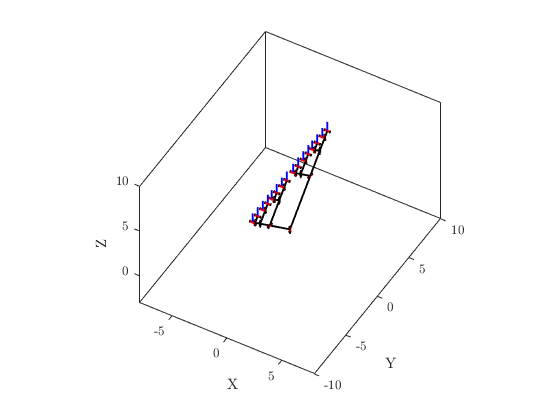

% inizializzazione della grafica del manipolatore
tree.FWKin(zeros(tree.Nb, 1));
tree.plotInit;
view(gca, 30, 45);
xlabel(gca, 'X');
ylabel(gca, 'Y');
zlabel(gca, 'Z');
set(gca, 'box', 'on')
xlim([-8 8]);
ylim([-10 10]);
zlim([-3 10]);

set(gcf,'Visible','on')

% inizializziamo passo e condizioni iniziali
deltaT = 0.005;                          % passo di integrazione
Vroot = [0;0;0;0;0;0];                   % twist alla base
Vrootdot = [0;0;9.81;0;0;0];             % simulate gravity by accelerating the base
Fext = zeros(6,tree.Nb);                 % external forces on each node
q = rand(tree.Nb, 1);
q(1) = 1.2;
qd = zeros(tree.Nb, 1);
x = [q; qd];

for i = 1:5000 % passi di integrazione
    % aggiornamo la postura
    tree.FWKin(x(1:tree.Nb));
    % aggiorniamo la grafica
    tree.updatePlot();
    % aggiorniamo il plot con pause(secondi) oppure drawnow()
    pause(0.01)
    % applichiamo delle molle e smorzatori ai giunti 
    tau = -x(tree.Nb+1:end).*linspace(6, 1, tree.Nb).'... forze di smorzamento
          -x(1:tree.Nb).*((tree.Nb:-1:1).').*linspace(100, 5, tree.Nb).'; % forze molle
    % applichiamo un passo di integrazione 
    x = full(RK4_step(x, [tau;Vroot;Vrootdot;Fext(:)], @xdot_mex, deltaT));
    % se non si ha un compilatore sostituire '@xdot_mex' con 'xdot_fun'

end

Error using kinematicTree/updatePlot (line 259)
no current plot to update exists, initialize the plot first with "treeObject.plotInit" 

% confrontiamo le prestazioni computazionali di una funzione compilata vs
% nativa matlab
q = rand(tree.Nb,1);
qd = rand(tree.Nb,1);
tau = rand(tree.Nb,1);
Vroot = rand(6, 1);
Vrootdot = rand(6, 1);
Fext = rand(6, tree.Nb);
tic;
iterations = 10000;
for i = 1:iterations
   xdot_mex([q; qd], [tau; Vroot; Vrootdot; Fext(:)]);
end
time = toc;
disp(iterations + " iterations of compiled ABA computed in: " + time + " seconds")
disp("average of " + time.*1000./(iterations) + " ms per iteration")

tic;
iterations = 10000;
for i = 1:iterations
   tree.ABAdyn(q,qd,tau,Vroot,Vrootdot,Fext);
end
time = toc;

disp(iterations + " iterations of ABA (native matlab) computed in: " + time + " seconds")
disp("average of " + time.*1000./(iterations) + " ms per iteration")